# Testing signals

This live script is to demonstrate the inner workings of the random signals. It performs exactly the same as the *rsignal *function, but here it is visualized and shown for clarification purposes.

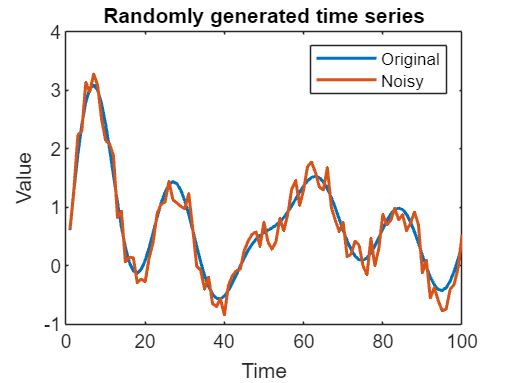

clear all;
format long;

% Generate sinusoidal signals
period = 1;
amp = 1;
dt = 1;
interval = 100;
t = (0:dt:interval)';

% Define base signals without decay and random addition
base_signal1 = amp*sin(2 * pi * period * round(rand()*0.1+0.01,2) * t);
base_signal2 = amp*sin(2 * pi * period * round(rand()*0.1+0.01,2) * t);
base_signal3 = amp*sin(2 * pi * period * round(rand()*0.1+0.01,2) * t);

% Determine option testing purposes
signal_option = 3;
noise_option = 1;

% Apply selected option
switch signal_option
    case 1
        % No decay or random addition
        signal1 = base_signal1;
        signal2 = base_signal2;
        signal3 = base_signal3;
    case 2
        % No random addition
        signal1 = base_signal1 .* exp(-0.01 * t);
        signal2 = base_signal2 .* exp(-0.01 * t);
        signal3 = base_signal3 .* exp(-0.01 * t);
    case 3
        % Everything (decay and random addition)
        signal1 = base_signal1 .* exp(-0.01 * t) + round(rand() * 10,2);
        signal2 = base_signal2 .* exp(-0.01 * t) - round(rand() * 10,2);
        signal3 = base_signal3 .* exp(-0.01 * t) + round(rand() * 10,2);
    case 4
        % No decay, random addition
        signal1 = base_signal1 + rand() * 10;
        signal2 = base_signal2 - rand() * 10;
        signal3 = base_signal3 + rand() * 10;
    otherwise
        error('Invalid option selected');
end

% Combine signals to form the time series
time_series = signal1 + signal2 + signal3;

%this parameter exist such that the learning part is always
%of constant length no matter how many predictions you
%want.
num_predict = 0;
lookout = num_predict - 1;
time_series = rsignal(period,amp,dt,interval+lookout);
N = length(time_series);

noise_param = 0.1;

noisy_series = noisify(noise_param,N,time_series);

% Plot the time series
figure;
plot(time_series, 'LineWidth', 1.5);
hold on;
plot(noisy_series, 'LineWidth', 1.5);
legend({"Original", "Noisy"})
hold off;
title('Randomly generated time series');
xlabel('Time');
ylabel('Value');

(1-2*round(rand()))*(0.5*rand(N,1)*rt)